syms f(x) X Y 
m1 = 0.1

m1 = 0.1000

m2 = 0.5

m2 = 0.5000

g = 9.8

g = 9.8000

lambda1 = 100

lambda1 = 100

lambda2 = -2

lambda2 = -2

Df = diff(f,x);
D2f = diff(f,x,2);
D3f = diff(f,x,3);
D4f = diff(f,x,4);
ode = m1*m2*D4f  == 0;
% cond1 = f(0)==0.4;
% cond2 = Df(0)==0;
% cond3 = D2f(0) == 0;
% cond4 = D3f(0) == 0;
[VF,Sbs] = odeToVectorField(ode)

$$VF = \left(\begin{array}{c} Y_{2}\\ Y_{3}\\ Y_{4}\\ 0 \end{array}\right)$$

$$Sbs = \left(\begin{array}{c} f\\ \mathrm{Df}\\ \mathrm{D2f}\\ \mathrm{D3f} \end{array}\right)$$

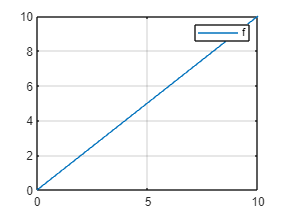

odefcn = matlabFunction(VF, 'Vars',{x,Y});
[X,Y] = ode45(odefcn, [0 10], [0 1 0 0]);
figure
plot(X, Y(:,1))
grid
legend(string(Sbs))